# Distribution Exact Savings Choices Vectorized

This is the example vignette for function: [**snw_ds_main_vec**](https://github.com/FanWangEcon/PrjOptiSNW/blob/master/PrjOptiSNW/sdist/snw_ds_main_vec.m) from the [**PrjOptiSNW Package**](https://fanwangecon.github.io/PrjOptiSNW/)**. **This function solves for vfi and gets distribution induced by policy functions and exogenous distributions. Vectorized vfi and distribution methods.

## Test SNW_DS_MAIN_VEC

Call the function with testing defaults.

mp_params = snw_mp_param('default_dense');
mp_controls = snw_mp_control('default_test');
mp_controls('bl_print_vfi') = false;
mp_controls('bl_print_ds') = true;
mp_controls('bl_print_ds_verbose') = false;
[Phi_true,Phi_adj,A_agg,Y_inc_agg,it,mp_dsvfi_results] = snw_ds_main_vec(mp_params, mp_controls);

Completed SNW_VFI_MAIN_BISEC_VEC;SNW_MP_PARAM=default_dense;SNW_MP_CONTROL=default_test;time=34.5151
----------------------------------------
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
CONTAINER NAME: mp_outcomes ND Array (Matrix etc)
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
                i    idx    ndim      numel       rowN    colN         sum         mean      std      coefvari      min         max    
                _    ___    ____    __________    ____    _____    ___________    ______    ______    ________    _______    __________

    V_VFI       1     1     

% [Phi_true,Phi_adj] = snw_ds_main(mp_params, mp_controls);
Phi_true = Phi_true/sum(Phi_true(:));

## Show All Info in mp_dsvfi_results

mp_cl_mt_xyz_of_s = mp_dsvfi_results('mp_cl_mt_xyz_of_s');
disp(mp_cl_mt_xyz_of_s('tb_outcomes'))

                       mean         sd       coefofvar      min         max       pYis0      pYls0      pYgr0      pYisMINY      pYisMAXY      p0_01        p0_1         p1          p5         p10         p20          p25           p30           p40         p50         p60         p70        p75        p80         p90        p95        p99       p99_9     p99_99     fl_cov_a_ss    fl_cor_a_ss    fl_cov_ap_ss    fl_cor_ap_ss    f

## Show Distribution by Age

Note that the age-distribution is exogenously determined by the age-specific survival rate. From: "load('Mortality_prob_by_age_18_99.mat','mort_prob') psi_full=1-mort_prob;".

First, we generate a vector for the age-specific mass, and visualize this.

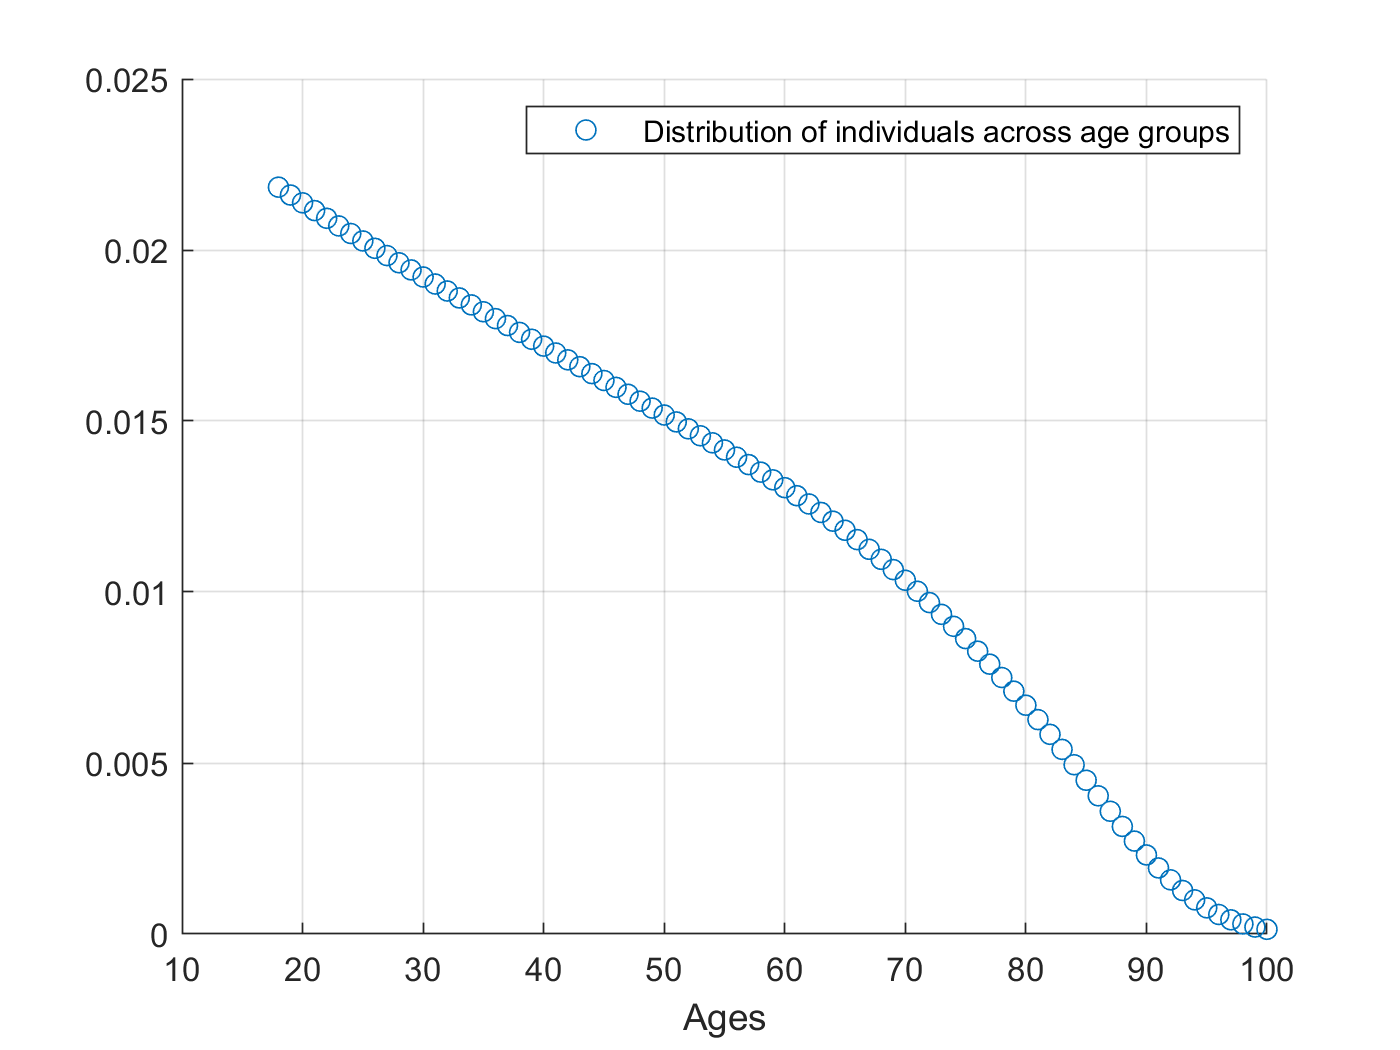

ar_fl_phi_true_age = NaN([size(Phi_true,1),1]);
for it_age_ctr=1:size(Phi_true,1)
  ar_fl_phi_true_age(it_age_ctr,1) = sum(Phi_true(it_age_ctr,:));
end
ar_ages = 18:(18+size(Phi_true,1)-1);
% Graph
figure();
h1 = scatter(ar_ages, ar_fl_phi_true_age);
grid on;
legend1 = sprintf('Distribution of individuals across age groups');
legend({legend1});
xlabel("Ages");

Second, given some overall age span from age Xl to Xu, we consider G segments within, and the conditional probability of mass in each of the G segments within Xl to Xu bounds.

% Overall prime-age
it_age_min = 18;
it_age_max = 65;
ar_ages_18t65 = ((ar_ages<=it_age_max) & (ar_ages>=it_age_min));
ar_fl_phi_true_age_18t65 = ar_fl_phi_true_age(ar_ages_18t65);
fl_total_mass_18t65 = sum(ar_fl_phi_true_age_18t65);
% Sub-segments
ar_it_lower = [18, 25, 55]';
ar_it_higher = [24, 54, 65]';
ar_fl_p_agegrp_condi_18t65 = NaN([length(ar_it_lower),1]);
for it_age_ctr=1:length(ar_it_lower)
  it_age_lower = ar_it_lower(it_age_ctr);
  it_age_higher = ar_it_higher(it_age_ctr);
  ar_ages_subgrp = ((ar_ages<=it_age_higher) & (ar_ages>=it_age_lower));
  ar_fl_phi_true_age_subgrp = ar_fl_phi_true_age(ar_ages_subgrp);
  ar_fl_p_agegrp_condi_18t65(it_age_ctr) = sum(ar_fl_phi_true_age_subgrp)/fl_total_mass_18t65;
end
disp(['sum of ar_fl_p_agegrp_condi_18t65=' num2str(sum(ar_fl_p_agegrp_condi_18t65))]);

sum of ar_fl_p_agegrp_condi_18t65=1


disp(table(ar_fl_p_agegrp_condi_18t65, ar_it_lower, ar_it_higher));

    ar_fl_p_agegrp_condi_18t65    ar_it_lower    ar_it_higher
    __________________________    ___________    ____________

             0.18278                  18              24     
             0.64041                  25              54     
             0.17681                  55              65     

